# NARXNET

Nonlinear autoregressive neural network with external input.

Le reti NARX (Nonlinear autoregressive with external input) possono imparare a prevedere una serie temporale dati i valori passati della stessa serie temporale,l'input di feedback, e un'altra serie temporale chiamata serie temporale esterna (o esogena).

È stata implementata questa ulteriore rete neurale basandoci sull'esempio riportato dalla documentazione MATLAB che utilizza il nostro stesso dataset. (*https://it.mathworks.com/help/deeplearning/gs/neural-network-time-series-prediction-and-modeling.html*)

## NARX in open loop

Esegue una previsione one-step ahead: la rete neurale riceve un'istanza di input corrente e genera una previsione per l'istante di tempo successivo. Quindi, in ogni passo temporale, la previsione si basa solo sui dati di input correnti e sull'output generato nel passo precedente (un solo passo in avanti)

clear
clc

data = load('phdata.dat');

u1 = data(:, 2);
u2 = data(:, 3);
y = data(:, 4);

X = [u1 u2];    % colonne
T = y;         % riga

trainFcn = 'trainlm';  % funzione di addestramento: Levenberg-Marquardt backpropagation

Vengono specificati dei delay per i dati di input (*inputDelays*) e i dati di feedback (*feedbackDelays*). 

L'insieme dei delay specifica di quanti passi temporali indietro (i dati passati) devono essere considerati come input per la rete neurale. 

Ad esempio, se si specificano *inputDelays* = 1:4 e *feedbackDelays* = 1:4, significa che i dati passati fino a 4 passi temporali indietro saranno considerati come input e feedback per la rete neurale.

L'utilizzo dei delay può essere utile per catturare la memoria del sistema e le relazioni dinamiche tra le variabili nel tempo (eventuali dipendenze temporali nelle serie di input). Ad esempio, nel caso di un processo di neutralizzazione del pH,** il pH corrente potrebbe dipendere non solo dai valori correnti dei reagenti di neutralizzazione, ma anche dai loro valori passati a causa della cinetica chimica coinvolta nel processo di neutralizzazione**. L'introduzione dei delay consente alla rete neurale di considerare questi effetti temporali e di adattarsi alle variazioni dinamiche nel sistema.

inputDelays = 1:4;              % il valore corrente dei dati di input sarà utilizzato insieme
                                % ai 4 valori precedenti come input nella rete neurale. 
                                
                                
feedbackDelays = 1:4;           % un ritardo nel feedback dell'output significa che il valore di 
                                % output precedente (in questo caso 4)viene utilizzato come parte
                                % dell'input per la previsione del valore corrente dell'output


hiddenLayerSize = 10;           % neuroni dell'hidden layer


net = narxnet(inputDelays,feedbackDelays,hiddenLayerSize,'open',trainFcn);
% con 'open' viene specificato il tipo di feedback: OPEN LOOP

net.numInputs = 2;

[x,xi,ai,t] = preparets(net,con2seq(X'),{},con2seq(T'));
% le parentesi graffe vuote indicano nessuna specifica per i Non-feedback targets

con2seq converte la matrice in una sequenza, nello specifico, invece di avere tutti gli elementi in un solo vettore/matrice, vengono considerati come singoli elementi separati di un dato con tante celle quanti sono gli elementi, tutto ciò perchè è richiesto dai comandi successivi.

La funzione *preparets* si occupa di organizzare i dati in forma di serie temporale per l'allenamento della rete neurale NARX. In particolare, restituisce i seguenti output:

- *x*: sequenza dei dati di input

- *xi*: vettore contenente gli stati iniziali della rete neurale, per gli input

- *ai*: vettore contenente gli stati iniziali della rete neurale, per gli strati nascosti

- *t*: sequenza dei dati di target.

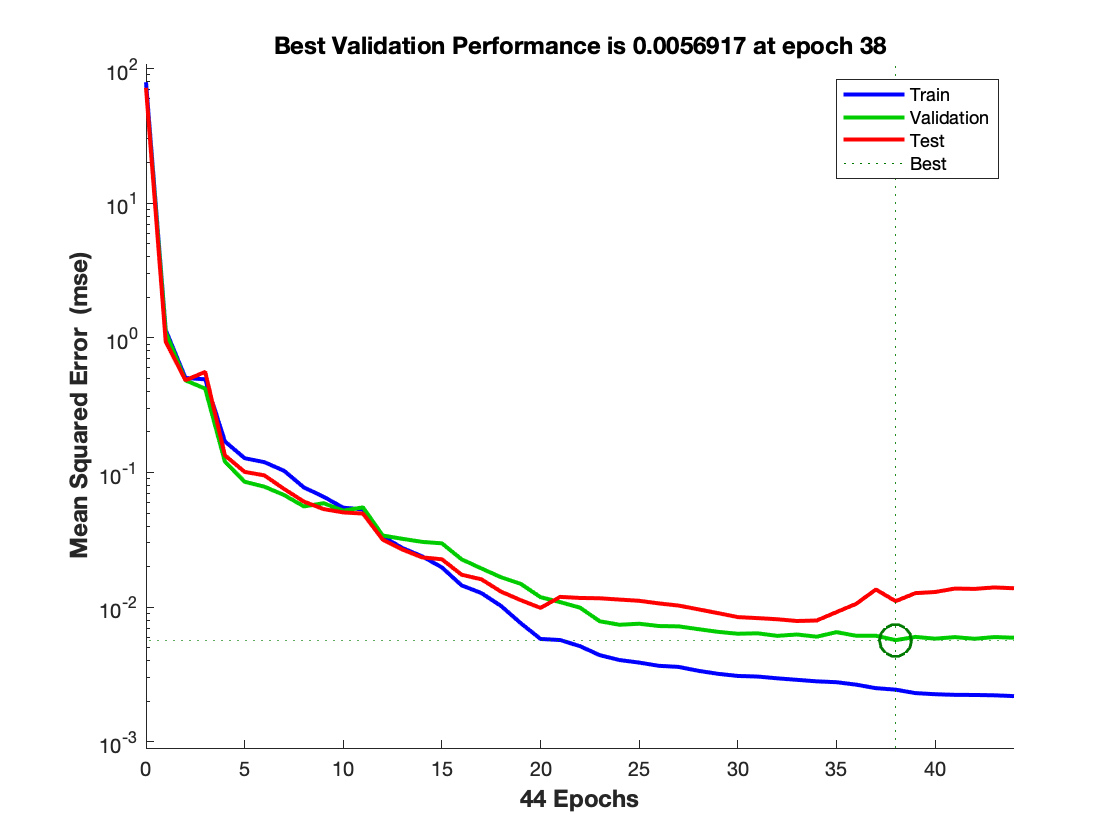

% definisco i mini-batch rispetto al dataset totale: training = 70% ; validation = 15% ; test = 15%

net.divideParam.trainRatio = 0.7;
net.divideParam.valRatio = 0.15;
net.divideParam.testRatio = 0.15;

net.trainParam.showWindow = false;                      % serve per togliere la finestra del Report (ridurre carico CPU)

[net,tr] = train(net,x,t,xi,ai);    % alleno la rete

% Viene testata la rete 
y = net(x,xi,ai);                   % vengono fatte delle previsioni, calcolo l'uscita dando in ingresso 
                                    % alla rete ciò che è stato definito prima

e = gsubtract(t,y);                 % calcola la differenza tra i due parametri in ingresso (y e t)→
                                    % → calcola l'errore tra i valori di target t 
                                    % e i valori di previsione y ottenuti dalla rete neurale

% view(net)
figure, plotperform(tr)

## NARX IN ANELLO CHIUSO

esegue previsione multistep-ahead: generare previsioni per più istanti di tempo futuri, oltre a quello successivo (più passi in avanti). Tutte le previsioni in avanti effettuate ritornano in ingresso alla rete e una volta che ha prodotto la nuova uscita (in base all'istante di tempo) ricontrolla con il valore che aveva previsto in precedenza (anche 3 step precedenti) e si corregge al bisogno. 

netc = closeloop(net);
netc.name = [net.name ' - Closed Loop'];        % viene dato un nome alla nuova rete il anello chiuso

effettuo il closed loop sulla rete neurale. L'output della rete viene utilizzato come input all'istante di tempo successivo. Riceve un feedback dei suoi stessi output precedenti rendendola potenzialmente più precisa.

% view(netc)
% effettuo gli stessi passaggi visti in precedenza ma con la nuova rete in anello chiuso

[xc,xic,aic,tc] = preparets(netc,con2seq(X'),{},con2seq(T'));
yc = netc(xc,xic,aic);

## NARX senza ritardi

%nets = removedelay(net);
nets = narxnet([],[],hiddenLayerSize,'open',trainFcn);

nets.numInputs = 2;

Rimuove il ritardo dalla rete. Crea una nuova rete neurale a partire da una rete NARX esistente, rimuovendo i ritardi temporali associati ai dati di input e di feedback dell'output. (quelli specificati a riga 11 e riga 14)

Effettua previsioni "one-step-ahead" senza considerare i valori di input e di output precedenti;  la previsione corrente si basa solo sui dati di input correnti.

% nets.name = [nets.name ' - Predict One Step Ahead'];
% view(nets)
% effettuo gli stessi passaggi visti in precedenza ma con la nuova rete senza ritardi

[xs,xis,ais,ts] = preparets(nets,con2seq(X'),{},con2seq(T'));

nets.divideParam.trainRatio = 0.7;
nets.divideParam.valRatio = 0.15;
nets.divideParam.testRatio = 0.15;

nets.trainParam.showWindow = false;                      % serve per togliere la finestra del Report (ridurre carico CPU)

[nets,trs] = train(nets,xs,ts,xis,ais);       % alleno la rete

ys = net(xs,xis,ais);   

## Calcolo del Fit per le tre varianti di Reti NARX

Per il calcolo dei coefficienti è stato utilizzato il comando *cell2mat()* che converte una cella di array (ciò che si ottiene con con2seq) in una matrice.

% Calcolo del coefficiente di correlazione
corr = corrcoef(cell2mat(t)', cell2mat(y)');
y = cell2mat(y);
mse_D = mse(y, T);
mse_D = mse(y', T((size(T,1)-size(y,2))+1: size(T,1)));
fit_percent = corr(1, 2) * 100

fit_percent = 99.9693

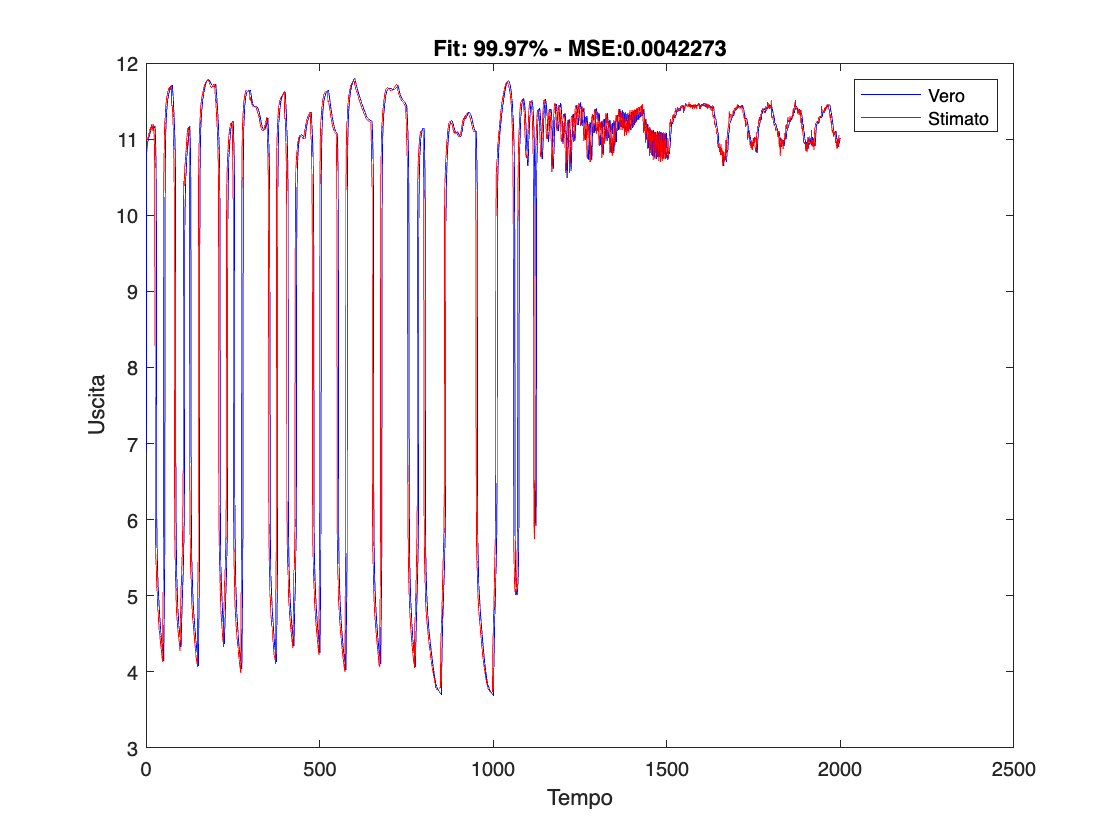

figure (315)
%clf;
plot(T, 'b');
hold on;
plot(y, 'r');
xlabel('Tempo');
ylabel('Uscita');
legend('Vero', 'Stimato');
title(['Fit: ' num2str(fit_percent, '%.2f') '% - MSE:' num2str(mse_D) ]);
hold off

% Calcolo del coefficiente di correlazione
corr = corrcoef(cell2mat(tc)', cell2mat(yc)');
yc = cell2mat(yc);
mse_C = mse(yc', T((size(T,1)-size(yc,2))+1: size(T,1)));
fit_percent_C = corr(1, 2) * 100

fit_percent_C = 78.6683

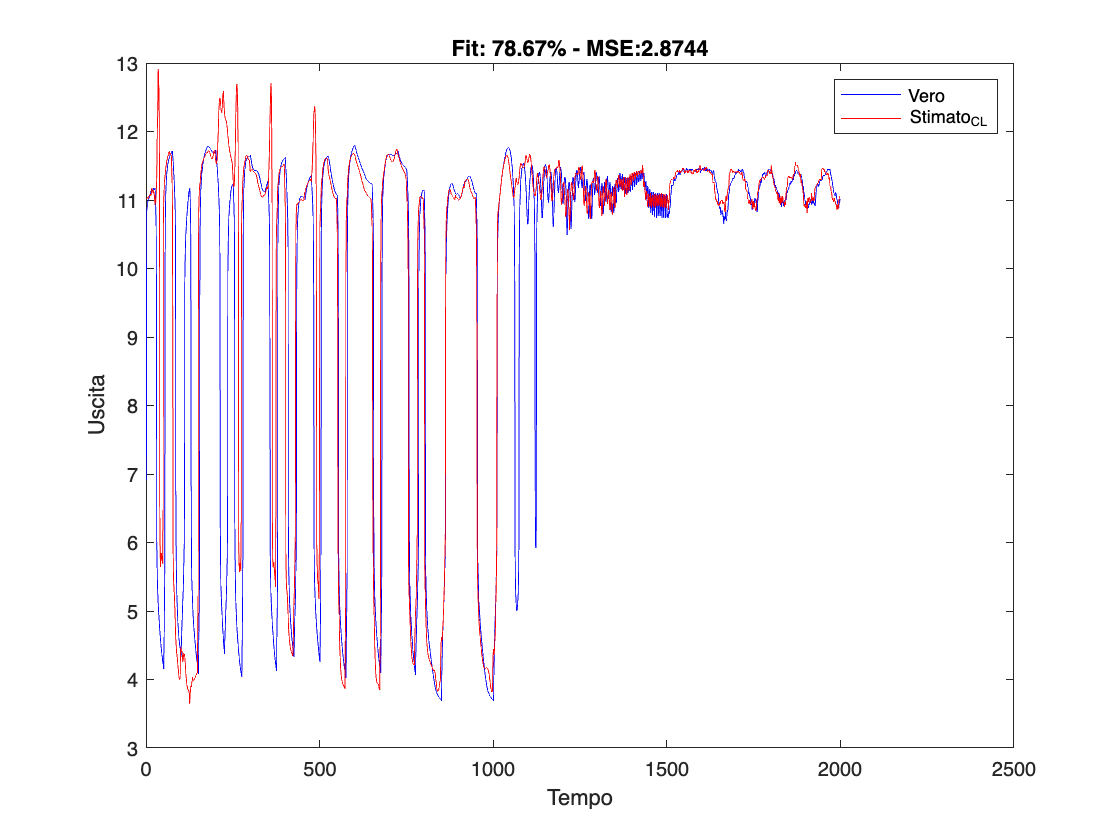

figure (320)
% clf;
plot(T, 'b');
hold on;
plot(yc, 'r');
xlabel('Tempo');
ylabel('Uscita');
legend('Vero', 'Stimato_{CL}');
title(['Fit: ' num2str(fit_percent_C, '%.2f') '% - MSE:' num2str(mse_C) ]); 
hold off

% Calcolo del coefficiente di correlazione
corr = corrcoef(cell2mat(ts(:,1:end-1))', cell2mat(ys(:,1:end-1))');
ys = cell2mat(ys);
mse_S = mse(ys', T((size(T,1)-size(ys,2))+1: size(T,1)));
fit_percent_S = corr(1, 2) * 100

fit_percent_S = 99.9228

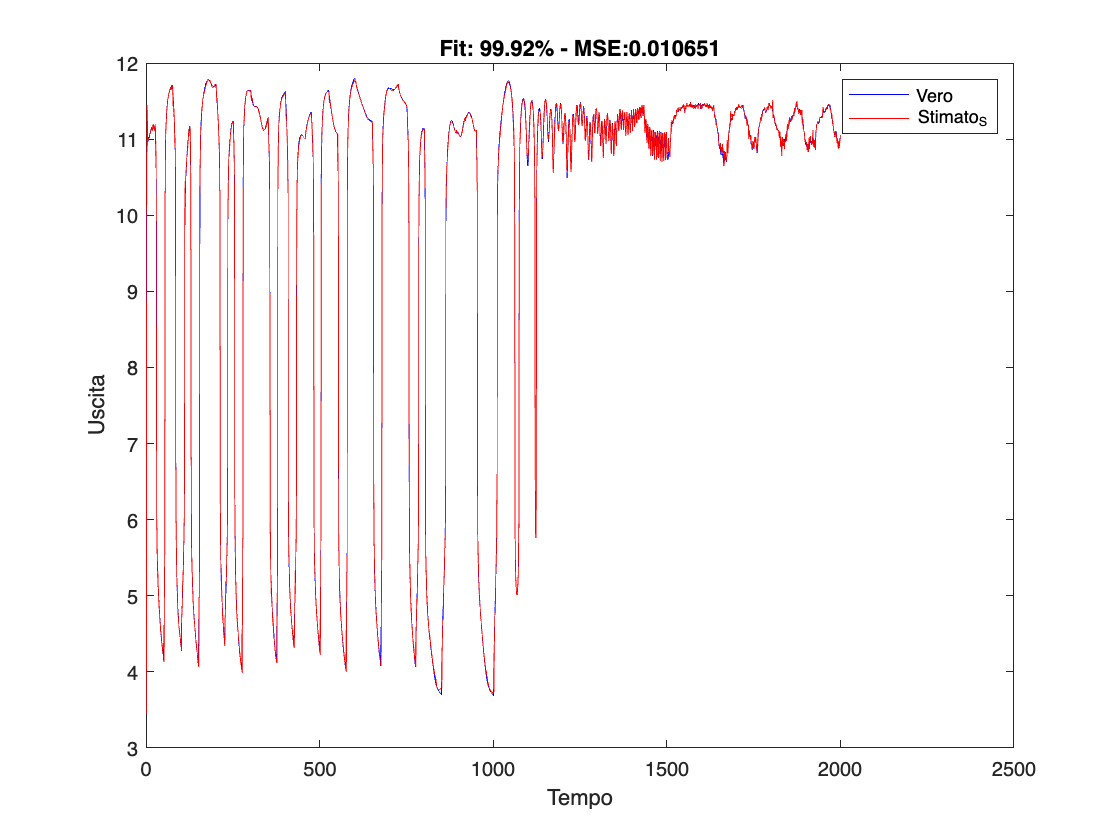

figure (325)
% clf;
plot(T, 'b');
hold on;
plot(ys, 'r');
xlabel('Tempo');
ylabel('Uscita');
legend('Vero', 'Stimato_S');
title(['Fit: ' num2str(fit_percent_S, '%.2f') '% - MSE:' num2str(mse_S) ]); 
hold off 